# **Fig 4 - Impact of Mobility Pattern on EV charging**

## **Number of parked vehicles - By aggregating the number of vehicles in each planning area for a day.**

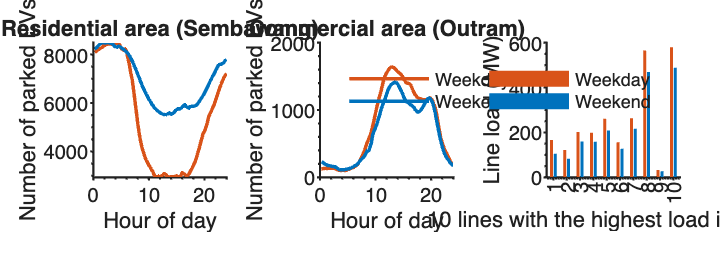

clear all; close all; clc;

%% --- Load data (parked vehicles) ---
filename_SEMBAWANG          = '../data/ParkedVehNumberData/ParkedVehData_SEMBAWANG.csv';
filename_SEMBAWANG_weekend  = '../data/ParkedVehNumberData/ParkedVehData_SEMBAWANG_weekend.csv';
filename_OUTRAM             = '../data/ParkedVehNumberData/ParkedVehData_OUTRAM.csv';
filename_OUTRAM_weekend     = '../data/ParkedVehNumberData/ParkedVehData_OUTRAM_weekend.csv';

ParkedVehData_SEMBAWANG = [readmatrix(filename_SEMBAWANG), readmatrix(filename_SEMBAWANG_weekend)];
ParkedVehData_OUTRAM    = [readmatrix(filename_OUTRAM),    readmatrix(filename_OUTRAM_weekend)];

t = (0.25:0.25:24)';   


max_load_table = readtable('../data/Data4Figure/Weekday_weekend_data.csv');
max_load = max_load_table{:,:};


col_weekday = 4;
col_weekend = 10;


max_load_increase = (max_load(:, col_weekend) - max_load(:, col_weekday)) ./ max_load(:, col_weekday);

[~, colIndices] = sort(max_load_increase, 'ascend');

num_line_to_show = 10;
top_idx = colIndices(1:num_line_to_show);

Y_weekday = max_load(top_idx, col_weekday);
Y_weekend = max_load(top_idx, col_weekend);

%% --- Colors (fixed & consistent) ---
cWeekday = [0.8500 0.3250 0.0980];  % red
cWeekend = [0.0000 0.4470 0.7410];  % blue




cGrid  = 0.85*[1 1 1];

%% --- Figure (1×3) ---
figure('Units','centimeters','Position',[2 2 18.3 6.5]); % two-column width, short height

tiledlayout(1,3,'Padding','compact','TileSpacing','compact');

% ---------- (1) Residential (Sembawang) ----------
nexttile; hold on;
plot(t, smoothdata(ParkedVehData_SEMBAWANG(:,1),'movmean',3), '-', 'Color', cWeekday, 'LineWidth', 1.3, 'DisplayName','Weekday');
plot(t, smoothdata(ParkedVehData_SEMBAWANG(:,2),'movmean',3), '-', 'Color', cWeekend, 'LineWidth', 1.3, 'DisplayName','Weekend');
xlabel('Hour of day');
ylabel('Number of parked EVs');
title('Residential area (Sembawang)');
xlim([0 24]);


% ---------- (2) Commercial (Outram) ----------
nexttile; hold on;
plot(t, smoothdata(ParkedVehData_OUTRAM(:,1),'movmean',3), '-', 'Color', cWeekday, 'LineWidth', 1.3, 'DisplayName','Weekday');
plot(t, smoothdata(ParkedVehData_OUTRAM(:,2),'movmean',3), '-', 'Color', cWeekend, 'LineWidth', 1.3, 'DisplayName','Weekend');
xlabel('Hour of day');
ylabel('Number of parked EVs');
title('Commercial area (Outram)');
xlim([0 24]); 
legend('Location','northwest','Box','off');


% ---------- (3) Top-N lines by load increase (grouped bars) ----------
nexttile; hold on;
X = 1:num_line_to_show;
Y = [Y_weekday, Y_weekend];   % columns = [Weekday Weekend]
bh = bar(X, Y, 'grouped', 'BarWidth', 0.8);


bh(1).FaceColor = cWeekday;  bh(1).EdgeColor = 'none';
bh(2).FaceColor = cWeekend;  bh(2).EdgeColor = 'none';

xlabel(sprintf('%d lines with the highest load increase', num_line_to_show));
ylabel('Line load (MW)');
xlim([0.5, num_line_to_show+0.5]);
xticks(X); xticklabels(string(X));
legend({'Weekday','Weekend'},'Location','northeast','Box','off');

set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

ax = findall(gcf,'Type','axes');
for k = 1:numel(ax)
    ax(k).FontSize = 7.5;
    ax(k).LineWidth = 0.8;
    ax(k).TickDir = 'out';
    ax(k).Box = 'off';
    ax(k).XMinorTick = 'on';
    ax(k).YMinorTick = 'on';
    ax(k).TickLength = [0.015 0.01];
end

drawnow;
for k = 1:numel(ax)
    outerpos = ax(k).OuterPosition; ti = ax(k).TightInset;
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);

end


%{ %}
% Export vector PDF
outdir = '../results'; if ~exist(outdir,'dir'), mkdir(outdir); end
exportgraphics(gcf, fullfile(outdir,"Fig4_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf"), ...
    'ContentType','vector','BackgroundColor','none');

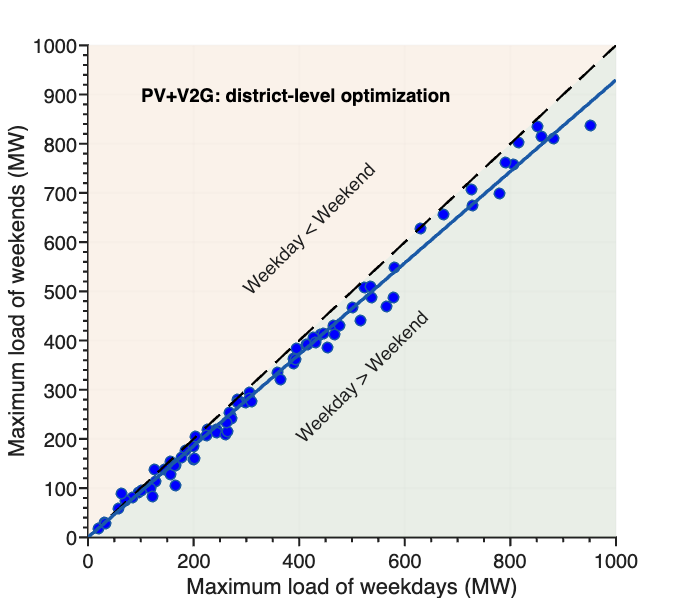


x = max_load(:, 4);        
y = max_load(:, 10); 


fig_w_cm = 9;   
fig_h_cm = 8;  
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);


set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

base_pt  = 7.5;    
label_pt = 8.5;    
line_w   = 1.1;
gridCol  = 0.85*[1 1 1];


colBlue      = [0.20 0.50 0.80];
colBlueDark  = [0.10 0.35 0.65];
colRed       = [0.80 0.30 0.30];
colRedDark   = [0.65 0.15 0.15];

lightRed   = [245,229,214]./255;
lightGreen = [211,222,208]./255;

x_min = 0; x_max = 1000;
y_min = 0; y_max = 1000;


idx = x >= x_min & x <= x_max;  
x = x(idx); y = y(idx);

hold on; box on;


fill([x_min x_max x_max x_min], [y_min y_min y_max y_min], lightGreen, 'EdgeColor','none', 'FaceAlpha',0.5);
fill([x_min x_max x_min x_min], [y_max y_max y_min y_max], lightRed, 'EdgeColor','none', 'FaceAlpha',0.5);

scatter(x, y, 15, 'b', 'filled', 'MarkerEdgeColor', colBlueDark, 'LineWidth',0.6);

plot([x_min, x_max], [x_min, x_max], 'k--', 'LineWidth', 0.9);


slope = (x(:)' * y(:)) / (x(:)' * x(:));
x_fit = 0:10:1000;
y_fit = slope .* x_fit;
plot(x_fit, y_fit, '-', 'Color', colBlueDark, 'LineWidth', line_w+0.2, ...
    'DisplayName', sprintf('Fit: y = %.3fx', slope));

xlabel("Maximum load of weekdays (MW)", 'FontSize', label_pt);
ylabel('Maximum load of weekends (MW)', 'FontSize', label_pt);
xlim([x_min, x_max]); ylim([y_min, y_max]);
grid on; ax = gca; ax.GridColor = gridCol;

set(ax, 'FontSize', base_pt, 'TickDir','out', 'LineWidth',0.8, ...
    'Box','off', 'XMinorTick','on', 'YMinorTick','on', 'TickLength',[0.015 0.01]);

pct_change = (y - x) ./ x * 100;
mean_pct   = mean(pct_change);
std_pct    = std(pct_change);

text(300, 500, 'Weekday < Weekend', 'FontSize', 7, 'Rotation', 45, 'FontWeight', 'normal');
text(400, 200, 'Weekday > Weekend', 'FontSize', 7, 'Rotation', 45, 'FontWeight', 'normal');

text(100, 900, sprintf("PV+V2G: district-level optimization"), ...
     'FontSize', 7, 'FontWeight', 'bold', 'Color', 'k');

hold off;


%{  %}
%% ---------------- Export (vector PDF) ----------------
outPath = "../results/All_line_weekday_weekend_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');

%{ %}

